Fi = 1e3

Fi = 1000

Fs = 2e5

Fs = 200000

Tstop = 0.15

Tstop = 0.1500

mdl = "class_d_ff"

mdl = "class_d_ff"

simin = Simulink.SimulationInput(mdl)

simin =   SimulationInput with properties:

               ModelName: "class_d_ff"
            InitialState: [0×0 Simulink.op.ModelOperatingPoint]
           ExternalInput: []
         ModelParameters: [0×0 Simulink.Simulation.ModelParameter]
         BlockParameters: [0×0 Simulink.Simulation.BlockParameter]
               Variables: [0×0 Simulink.Simulation.Variable]
               PreSimFcn: []
              PostSimFcn: []
              UserString: ''
    VariantConfiguration: ''



simin = setModelParameter(simin, ...
    "StopTime", string(Tstop))

simin =   SimulationInput with properties:

               ModelName: "class_d_ff"
            InitialState: [0×0 Simulink.op.ModelOperatingPoint]
           ExternalInput: []
         ModelParameters: [1×1 Simulink.Simulation.ModelParameter]
         BlockParameters: [0×0 Simulink.Simulation.BlockParameter]
               Variables: [0×0 Simulink.Simulation.Variable]
               PreSimFcn: []
              PostSimFcn: []
              UserString: ''
    VariantConfiguration: ''


input = strcat(mdl, "/Sine Wave")

input = "class_d_ff/Sine Wave"

simin = setBlockParameter(simin, input, "Frequency", string(2*pi*Fi))

simin =   SimulationInput with properties:

               ModelName: "class_d_ff"
            InitialState: [0×0 Simulink.op.ModelOperatingPoint]
           ExternalInput: []
         ModelParameters: [1×1 Simulink.Simulation.ModelParameter]
         BlockParameters: [1×1 Simulink.Simulation.BlockParameter]
               Variables: [0×0 Simulink.Simulation.Variable]
               PreSimFcn: []
              PostSimFcn: []
              UserString: ''
    VariantConfiguration: ''



output = strcat(mdl, "/Sampled Output")

output = "class_d_ff/Sampled Output"

simin = setBlockParameter(simin, output, "SampleTime", string(1/Fs))

simin =   SimulationInput with properties:

               ModelName: "class_d_ff"
            InitialState: [0×0 Simulink.op.ModelOperatingPoint]
           ExternalInput: []
         ModelParameters: [1×1 Simulink.Simulation.ModelParameter]
         BlockParameters: [1×2 Simulink.Simulation.BlockParameter]
               Variables: [0×0 Simulink.Simulation.Variable]
               PreSimFcn: []
              PostSimFcn: []
              UserString: ''
    VariantConfiguration: ''



out = sim(simin)

### Building the rapid accelerator target for model: class_d_ff
### Successfully built the rapid accelerator target for model: class_d_ff


out =   Simulink.SimulationOutput:

                   tout: [15706869x1 double] 
               discrete: [30001x1 double] 
             continuous: [1x1 struct] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


timeseries = get(out, "continuous")

timeseries = struct with fields:
         time: [15706869×1 double]
      signals: [1×1 struct]
    blockName: 'class_d_ff/Continuous Output'


sampled = get(out, "discrete")

sampled =          0
    0.3141
    0.9970
    1.6880
    2.3188
    3.0235
    3.6795
    4.3576
    5.0417
    5.7058


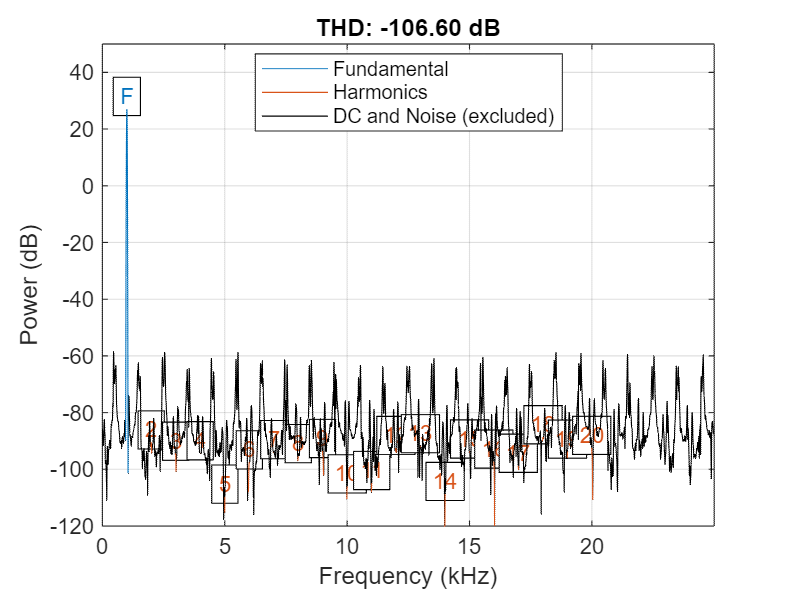

ans = -101.6838

thd(sampled,Fs,20)